close all; clear; clc;

# Turnigy 5 min run at 500 watts

**file name**:

**keywords:** 

**date of test:** 201903

**file created by:** 20181001, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

cutoff at 90 degrees is (1:25792)

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3]


% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

file1 = xlsread('RM_500W_5min_2bat.csv');
time2 = file1(:,1);                       % [sec]
PWM2 = file1(:,2);                        % [micro sec]
ESC_Temp2 = file1(:,14);                  % [F]
Motor_Temp2 = file1(:,15);                % [F]
Input_V2 = file1(:,6);                    % [Volts]
Input_A2 = file1(:,7);                    % [Amps]
rot_speed_rpm2 = file1(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad2 = rot_speed_rpm2 .* (pi/30);   % [rad/sec]
P_in_W2 = file1(:,9);                     % [Watts]
P_out_W2 = file1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out2 = P_out_W2 .* 0.7478;                  % [ft.lbf/sec]         
P_in2 = P_in_W2 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff2 = file1(:,11);                 % [%]
maxT2 = max(Motor_Temp2)

maxT2 = 80.3750

avg2 = mean(Input_V2)

avg2 = 23.2756


file2 = xlsread('RM_500W_5min_3bat.csv');
time3 = file2(:,1);                       % [sec]
PWM3 = file2(:,2);                        % [micro sec]
ESC_Temp3 = file2(:,14);                  % [F]
Motor_Temp3 = file2(:,15);                % [F]
Input_V3 = file2(:,6);                    % [Volts]
Input_A3 = file2(:,7);                    % [Amps]
rot_speed_rpm3 = file2(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad3 = rot_speed_rpm3 .* (pi/30);   % [rad/sec]
P_in_W3 = file2(:,9);                     % [Watts]
P_out_W3 = file2(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out3 = P_out_W3 .* 0.7478;                  % [ft.lbf/sec]         
P_in3 = P_in_W3 .* 0.7478;                    % [ft.lbf/sec]
maxT3 = max(Motor_Temp3)

maxT3 = 82.1750

avg3 = mean(Input_V3)

avg3 = 36.0390


file3 = xlsread('RM_500W_5min_4bat.csv');
time4 = file3(:,1);                       % [sec]
PWM4 = file3(:,2);                        % [micro sec]
ESC_Temp4 = file3(:,14);                  % [F]
Motor_Temp4 = file3(:,15);                % [F]
Input_V4 = file3(:,6);                    % [Volts]
Input_A4 = file3(:,7);                    % [Amps]
rot_speed_rpm4 = file3(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad4 = rot_speed_rpm4 .* (pi/30);   % [rad/sec]
P_in_W4 = file3(:,9);                     % [Watts]
P_out_W4 = file3(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out4 = P_out_W4 .* 0.7478;                  % [ft.lbf/sec]         
P_in4 = P_in_W4 .* 0.7478;                    % [ft.lbf/sec]
maxT4 = max(Motor_Temp4)

maxT4 = 89.3750

## Plots

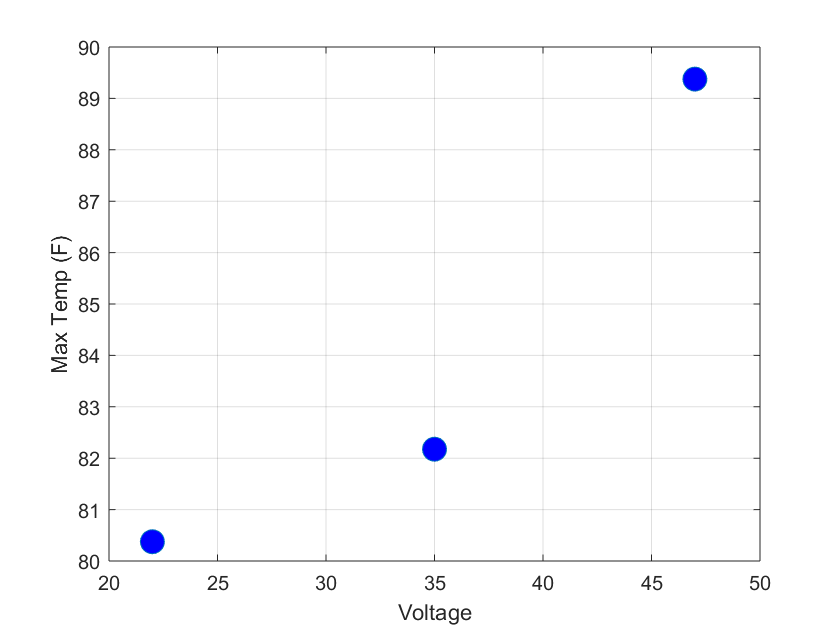

figure(1)
plot([22 35 47], [maxT2 maxT3 maxT4], 'o', 'MarkerSize', 12, 'MarkerFaceColor','b');
%plot(22, maxT2,'o', 35, maxT3, 'o', 47, maxT4, 'o', 'MarkerSize', '12' );
grid('on'); 
%title('KDE Constant Power (500 W)');
xlabel('Voltage'); ylabel('Max Temp (F)');